# MultiScale Truchet Patterns in MATLAB

## 1. パラメータの設定

パラメータを設定する．

- Resolution  : 生成される最小のタイルは一辺が5×Resolution [px] になる．

- n                 : 分割数．

- threshold    : Quadtree Decompositionの閾値．小さいほど細かく分割される．

res = 32;
n = 6;
threshold = 0.72;

## 2. 画像の読み込みとリサイズ

画像を一辺が2^nの正方形となるようにリサイズ

I = rgb2gray(imread("Aa.png"));
m = 2^n;
I_resized = imresize(I,[m,m]);

## 3. タイルの生成

論文のFigure 3, 4を参考にタイルを作成

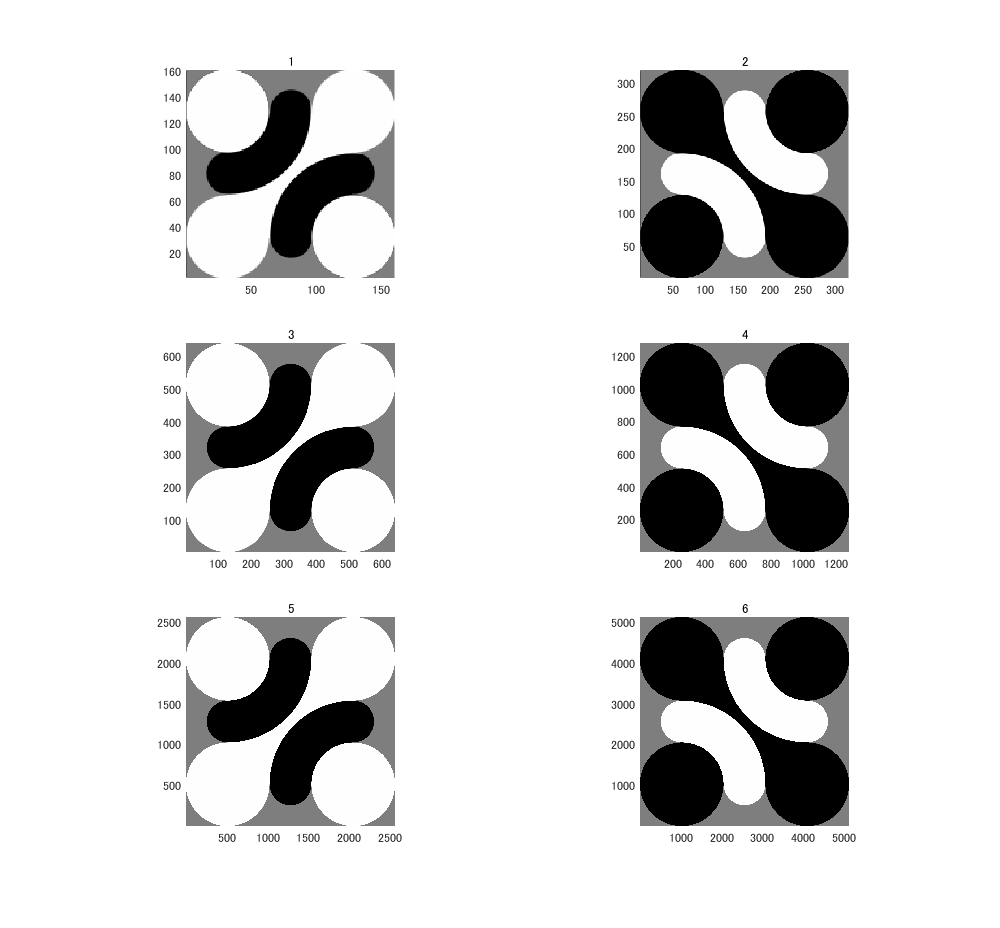

tiles = cell(n,1);

if res*2^(n-1)*5 > 2^20
    disp("Error : Maximum resolution exceeded the limitation")

else
    clf
    tiledlayout("flow")
    colormap gray
    
    for i = 1:n
        %calculate parts size
        base = res*2^(i-1);
        edge_min = base-0.5;
        edge_max = base*4+0.5;
        edge_cent = mean([edge_max edge_min])+0.5;
        
    
        %coloring
        color = zeros(base*5);
        color = insertShape(color,"FilledCircle", ...
            [edge_min,edge_min,base*2; ...
            edge_max,edge_max,base*2], ...
            "Color","white",'Opacity',1);
        color = insertShape(color,"FilledCircle", ...
            [edge_min,edge_min,base; ...
            edge_max,edge_max,base], ...
            "Color","black",'Opacity',1);
        if mod(i,2)==1
            color = 1-flip(color);
        end
        color = rgb2gray(color);
        
        
        %Masking
        mask = (zeros(base*5));
        mask(base-1:base*4,base-1:base*4) = 1;
        inner = color.*mask;
        outer = color.*(1-mask);
        
        
        %Generate alpha channel
        alpha = 255*zeros(base*5);
        alpha = insertShape(alpha,"FilledRectangle", ...
            [edge_min,edge_min,base*3,base*3], ...
            "LineWidth",1,"Color","white",'Opacity',1);
        alpha = insertShape(alpha,"FilledCircle", ...
            [edge_min,edge_min,base; ...
            edge_max,edge_max,base;
            edge_min,edge_max,base; ...
            edge_max,edge_min,base; ...
            edge_cent,edge_min,base/2; ...
            edge_cent,edge_max,base/2; ...
            edge_min,edge_cent,base/2; ...
            edge_max,edge_cent,base/2;], ...
            "Color","white",'Opacity',1);
        alpha = rgb2gray(alpha);
        
        
        %Return
        tile.inner = inner;
        tile.outer = outer;
        tile.alpha = alpha;
        tile.mask = mask;
        tiles{i} = tile;
        
        %Show tiles
        nexttile;
        hold on
        image(ones(base*5)*127);
        image(color*255,"AlphaData",alpha);
        pbaspect([1 1 1]);
        xlim([-inf inf]);
        ylim([-inf inf]);
        title(i)
        hold off
    end
end

## 4. Quadtree Decomposition & タイルの敷き詰め

画像に対してQuadtree decompositionを実行し，タイルを敷き詰める．

大きなタイルから先に敷き詰め，そのうえに小さなタイルを重ねる．

%calculate parts size
imsize = 4*res*2^(n);
margin = 1*res*2^(n-1);
base = 3*res;

%Quadtree Decomposition
S = qtdecomp(I_resized,threshold);
I_tiled = 255*ones(imsize);


%Tile each layer and composite
for i = fliplr(1:n)
    %Create temporary matrix
    TEMP_inner = zeros(imsize);
    TEMP_outer = zeros(imsize);
    TEMP_mask =  zeros(imsize);
    TEMP_alpha = zeros(imsize);
    
    
    %calculate parts size
    grid_size = 3*res*2^(i-1);
    tile_size = 5*res*2^(i-1);
    offset = res*2^(i-1);
    
    
    %Get nonzero elements of each layers 
    level = 2^(i-1);
    [X,Y] = find(S==level);
    idxs = 1:length(X);
    
    
    %Tile for each elements
    tile = tiles{i};
    for j = idxs
        %Get the position
        x = X(j);
        y = Y(j);
        
        %Get the indexes
        x_idxs = margin-offset+x*base+1: ...
                 margin-offset+x*base+tile_size;
        y_idxs = margin-offset+y*base+1: ...
                 margin-offset+y*base+tile_size;
        
        %Additive synthesis
        TEMP_inner(x_idxs,y_idxs) = max(TEMP_inner(x_idxs,y_idxs), ...
                                    tile.inner);
        TEMP_outer(x_idxs,y_idxs) = max(TEMP_outer(x_idxs,y_idxs), ...
                                    tile.outer);
        TEMP_mask(x_idxs,y_idxs) =  max(TEMP_mask(x_idxs,y_idxs), ...
                                    tile.mask);
        TEMP_alpha(x_idxs,y_idxs) = max(TEMP_alpha(x_idxs,y_idxs), ...
                                    tile.alpha);
    end
    
    %Layer synthesis
    TEMP_color = TEMP_inner.*TEMP_mask+TEMP_outer.*(1-TEMP_mask);
    I_tiled = TEMP_color.*TEMP_alpha + I_tiled.*(1-TEMP_alpha);
end

## 結果の表示

入力画像と出力画像の表示

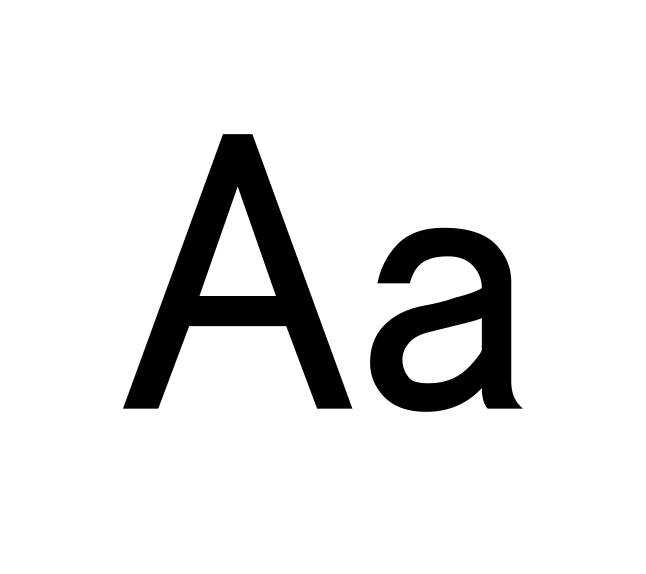

clf
imshow(I);

I_tiled = imresize(I_tiled,[1024 1024],"bilinear")

I_tiled =    255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   

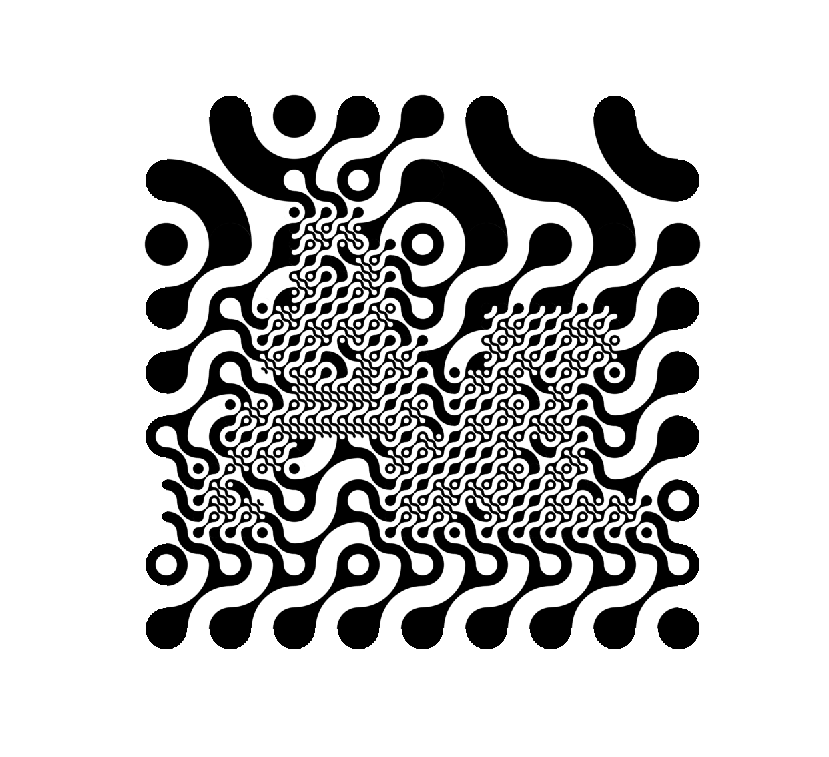

imshow(I_tiled);

imwrite(I_tiled,"result.png");

## 参考文献

[1] Carlson, Christopher. "Multi-Scale Truchet Patterns." *Bridges 2018 Conference Proceedings*. Tessellations Publishing, 2018.